Miniproject

1.  The function is shown at the end of this file

It is worth mentioned that switch or if structure is not used in the function. Instead, I choose to bulid an array that represents the number of the half tone based on C tone, which decreases the lines of coding.

2.  The function is shown at the end of this file

To transform the scale letters to the corresponding number, i took advantage of ASCII diagram and the remainder.

3.  The function is shown at the end of this file

4.  Attenuation function

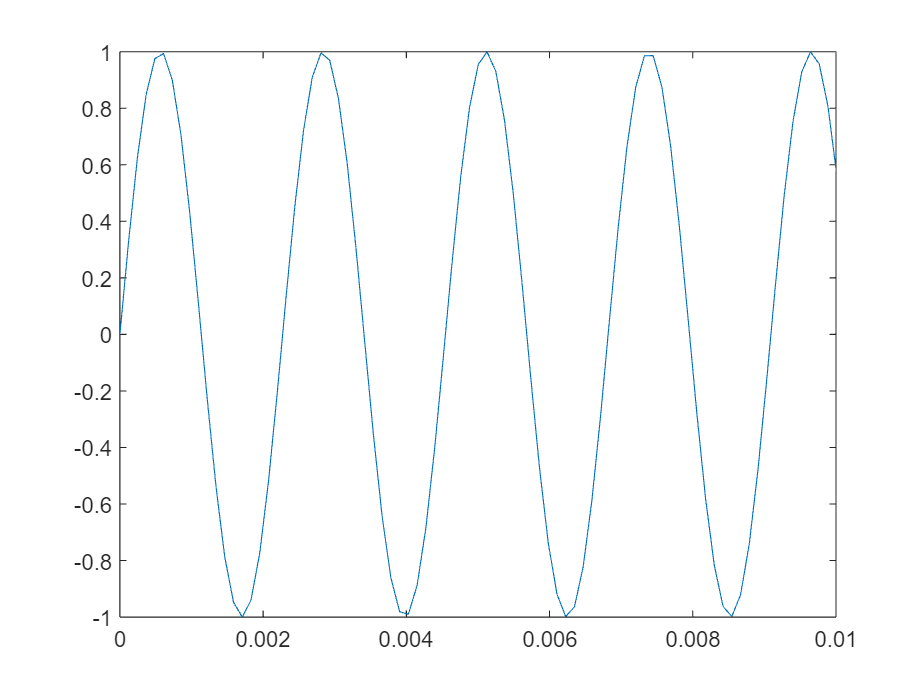

fs = 8192; f = 440; T = 1/f;
rhythm = 5;
t = linspace(0, rhythm, fs * rhythm);
y = sin(2*pi*f*t);
% Expotential Decay
waves = y.*exp(-t/rhythm);
%Hyperbolic Decay
waves1 = y.*(1./(t+1));
% Gaussian Decay
waves2 = y.*exp(-t.^2./4);
figure
plot(t,y);
axis([0 0.01 -1 1]);

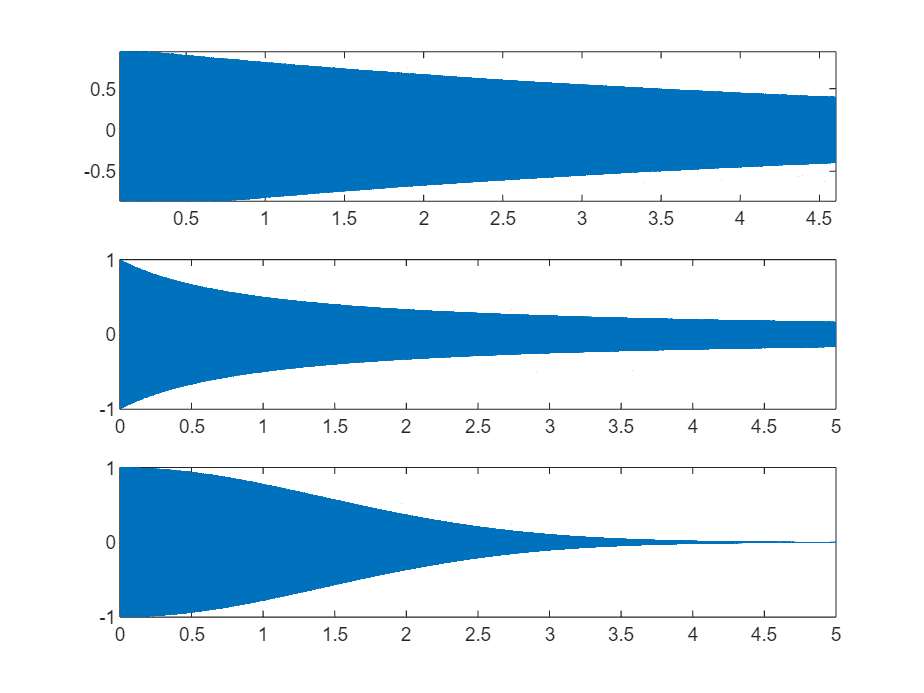

%sound(y, fs);
figure
subplot(3,1,1)
plot(t,waves);
axis([0 5 -1 1]);
%sound(waves, fs);
subplot(3,1,2)
plot(t,waves1);
axis([0 5 -1 1]);
%sound(waves1, fs);
subplot(3,1,3)
plot(t,waves2);
axis([0 5 -1 1]);

%sound(waves2, fs);

Here I used three different attenuation functions. And I think the sound processed by Gaussian function is the realest one. As the plots illustrate, expotential deacy is the slowest one while Gaussian dacay is the fatest one.

5. The tamber

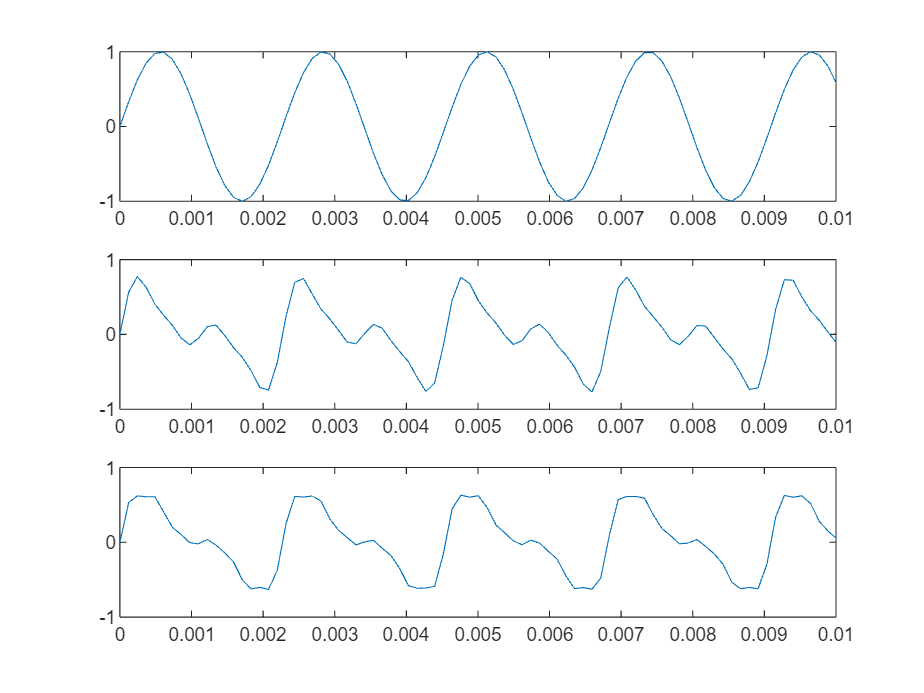

fs = 8192; f = 440; T = 1/f;
rhythm = 1;
t = linspace(0, rhythm, fs * rhythm);
y1 = 0.4*sin(2*pi*f*t)+0.4*sin(2*pi*2*f*t)+0.1*sin(2*pi*3*f*t)+0.1*sin(2*pi*4*f*t);
y = sin(2*pi*f*t);
y2 = 0.5*sin(2*pi*f*t)+0.3*sin(2*pi*2*f*t)+0.05*sin(2*pi*3*f*t)+0.05*sin(2*pi*4*f*t)+0.05*sin(sin(2*pi*5*f*t))+0.05*sin(2*pi*6*f*t);
figure
subplot(3,1,1)
plot(t,y);
axis([0 0.01 -1 1]);
%sound(y, fs);
subplot(3,1,2)
plot(t,y1);
axis([0 0.01 -1 1]);
subplot(3,1,3)
plot(t,y2);
axis([0 0.01 -1 1]);

sound(y1,fs);

当使用更多的谐波时，音色会变得越来越厚重。当增加高次谐波的比例时，音色会变亮，更具有穿透力。总体来说，添加谐波会使得信号的振幅变小。

fs = 44100;
scale = 'F';
tone = [0 1 3 3 0 0 0 1 4 3 4 3 4 5 3 3 0 0 0 1 4 3 4 3 4 5 3 3 0 0 0 1 2 1 2 1 2 3 2 2 1 6 0 0 2 2 1 2 2 0 0 0 1 3 3 0 0 0 1 4 3 4 3 4 5 3 3 0 0 0 1 4 3 4 3 4 5 3 3 2 3 2 1 0 0 1 2 1 2 1 2 3 2 2 1 6 0 0 3 2 1 2 2 3 2 0 0 5 6 5 5 4 3 3 2 3 0 0 0 5 6 6 5 5 4 5 5 3 2 3 3 3 2 1 0 5 1 1 7 7 6 5 3 3 2 3 2 1 0 5 6 1 1 6 1 5 5 3 3 3 3 3 4 3 2];
noctave = [zeros(1,41) -1 zeros(1,53) -1 zeros(1,40) 1 1 0 0 0 0 0 0 1 1 1 1 0 0 0 1 1 0 1 0 0 1 1 1 1 1 1 1 1];
rising = [zeros(1,108) 1 zeros(1,11) 1 zeros(1,17) 1 0 1 zeros(1,24)];
a = 0.5;%一个四分音符
rhythm = a.*[0.5 0.5 0.5 0.5 1 1 0.5 0.5 0.5 0.5 0.5 0.5 1 0.5 0.5 1 1 1 0.5 0.5 0.5 0.5 0.5 0.5 1 0.5 0.5 1 1 1 0.5 0.5 0.5 0.5 0.5 0.5 1 0.5 0.5 0.25 0.25 0.5 1 0.5 0.5 0.25 0.25 0.5 1 1 1 0.5 0.5 0.5 0.5 1 1 0.5 0.5 0.5 0.5 0.5 0.5 1 0.5 0.5 1 1 1 0.5 0.5 0.5 0.5 0.5 0.5 1 0.5 0.5 0.25 0.25 0.25 0.25 1 1 0.5 0.5 0.5 0.5 0.5 0.5 1 0.5 0.5 0.25 0.25 0.5 1 0.5 0.5 0.25 0.25 0.5 1 0.5 0.5 1 0.5 0.5 1.5 0.5 0.5 1 0.5 0.5 0.25 0.25 1 1 0.5 0.5 1 0.5 0.5 0.5 1 0.5 0.5 0.25 0.25 0.5 0.5 0.25 0.25 0.5 0.5 0.5 1 0.5 0.5 0.5 1 0.5 0.5 0.5 0.5 0.25 0.25 1 0.5 0.5 0.5 0.5 0.5 0.5 1 0.5 0.5 0.5 0.5 0.5 0.5 1.5 0.25 0.25 2];
re = gen_music(tone,scale,noctave,rising,rhythm,fs);
audiowrite('普通朋友.wav',re,fs);

sound(re,fs)

% scale1 = 'B';
% tone1 = [0 3 3 1 7 1 3 3 0 3 5 5 6 4 0 2 2 7 6 7 2 2 0 2 5 4 4 4 5 3 0 3 3 1 7 1 1 3 0 3 6 1 3 2 2 0 1 1 1 7 2 1 1 1 7 7 0 3 3 1 7 1 3 3 0 3 5 5 5 6 4 0 2 2 7 6 7 2 2 0 2 5 4 4 4 5 3 0 3 3 1 7 1 3 0 3 6 1 3 2 2 0 1 1 7 7 1 7 7 6 6 0 6 7 1 1 2 7 6 5 5 3 5 6 6 6 7 1 7 1 1 4 4 3 0 7 1 2 3 1 3 1 3 3 1 2 3 5 4 4 4 2 1 7 6 5 5 5 6 7 4 3 2 3 3 3 6 7 1 7 1 7 0 6 7 1 3 2 2 0 2 3 2 1 0 1 2 1 7 7 1 7 7 6 6];
% noctave1 = [0 0 0 1 0 1 zeros(1,27) 1 0 1 1 0 0 0 0 1 1 1 1 0 1 1 1 0 1 1 1 1 0 0 0 0 0 1 0 1 zeros(1,28) 1 0 1 0 0 0 0 1 1 1 1 0 1 1 0 0 1 0 0 0 0 0 0 0 1 1 1 zeros(1,10) 1 0 1 1 1 1 1 0 0 ones(1,17) zeros(1,7) ones(1,5) 0 0 0 1 0 1 0 0 0 0 ones(1,4) 0 ones(1,4) 0 1 1 1 0 0 1 0 0 0 0];
% rising1 = zeros(1,195);
% save('tone1',"tone1");
% save('noctave1',"noctave1");
% temp = [tone1;noctave1];
% b = 0.6;
% %da- dada
% b1 = [0.5 0.25 0.25];
% %dada
% b2 = [0.5 0.5];
% b3 = [0.25 0.25];
% %dadadada
% b4 = [0.25 0.25 0.25 0.25];
% rhythm1 = b.*[b1 b2 1.5 b3 1 b2 1.5 b3 b1 b2 1.5 b3 b2 b2 1 b1 b1 b2 1.5 b3 b2 b2 1.5 0.5 1 b2 1.5 0.5 1 b1 b2 1 b1 b2 1.5 b3 1 b1 1.5 b3 b1 b2 1.5 b3 b2 b2 1 b1 b1 b2 1.5 0.5 b2 b2 1.5 0.5 1 b2 2 1 b1 b2 1 b2 b2 2 1 b1 1 b1 1 b2 2 0.75 0.25 b2 4 2 b2 b2 b2 b1 b2 b2 1.5 b3 2 b2 b1 b2 b2 1 b1 b2 b2 b2 b2 b2 b2 1.5 0.5 1 b4 1 b4 1 b1 b2 3];
% re1 = gen_music(tone1,scale1,noctave1,rising1,rhythm1,fs);
% sound(re1,fs);
% %audiowrite('月半小夜曲.wav',re1,fs);

在演奏音乐中，我尝试模仿笛子的音色，通过网络搜索笛子的频谱图，我将谐波的比例调整为1：1：1：1。但最后的发生效果存在差距，缺少笛子的空灵感和悠扬感。

这次的projec很有意思。我学会了阅读简谱，知到了不少的专业知识，简谱中符号的含义是什么。其次是对音色的模仿，通过google，发现对乐器音色和频谱的分析似乎有不少的学术论文，最典型的是ASMR模型对钢琴音色的构建。人类所发明的乐器往往具有复杂，规律的频谱，和谐的音色，这是目前机器所难以模仿的，让人不禁感叹乐器发明者的智慧。

function freq = tone2freq(tone,scale,noctave,rising)
num = [0 2 3 5 7 9 10];
init_freq = 261.5;
half = power(2,1/12);
%转换调号为数字
sc_num = mod(abs(scale)-67,7)+1;
%计算不同调号下的主频
main_freq = init_freq*power(half,num(sc_num));
%主音含半音升降的情况
%main_freq = init_freq*power(half,num(sc_num))*power(half,-1);
%计算音符频率
if tone == 0
    freq = 0;
else 
    freq = main_freq*power(half,num(tone))*power(2,noctave)*power(half,rising);
end
end

function waves = gen_wave(tone,scale,noctave,rising,rhythm,fs)
t = linspace(0,rhythm,fs*rhythm);
f = tone2freq(tone,scale,noctave,rising);
if f == 0
    waves = zeros(1,length(t));
else 
    y =sin(2*pi*f*t)+0.6*sin(2*pi*2*f*t)+0.4*sin(2*pi*3*f*t)+0.3*sin(2*pi*4*f*t)+0.1*sin(2*pi*5*f*t)+0.1*sin(2*pi*6*f*t)+0.1*sin(2*pi*7*f*t)+0.08*sin(2*pi*8*f*t)+0.05*sin(2*pi*9*f*t)+0.03*sin(2*pi*10*f*t);
    waves = y.*exp(-t.^2./4);
end
%sound(waves,fs);
end

function  s = gen_music(tone,scale,noctave,rising,rhythm,fs)
s = [];
len = length(tone);
for i = 1:len
    te = gen_wave(tone(i),scale,noctave(i),rising(i),rhythm(i),fs);
    s = [s te];
end
end